### Assumptions:

    1. Small angles: $\sin \left(\theta \;\right)=\theta \;$

clear all
k = [100,100,100,100];
c = [0,0,0,0];


syms m1 m2 m3 I1 % mass 1,2,3 & inertia for M1
syms k1 k2 k3 k4 % spring constants
syms c1 c2 c3 c4 % damping constants
syms L1 L2 %distance of point A & B to the centre of M1



syms x1 x1_dot x1_ddot % displacement, velocity & acceleration of M1
syms x2 x2_dot x2_ddot % displacement, velocity & acceleration of M2
syms x3 x3_dot x3_ddot % displacement, velocity & acceleration of M3

syms theta theta_dot theta_ddot % angluar displacement, velocity & acceleration of M1

syms uA uA_dot % displacement applied by external force to point A of M1.
syms uB uB_dot % displacement applied by external force to point B of M1.






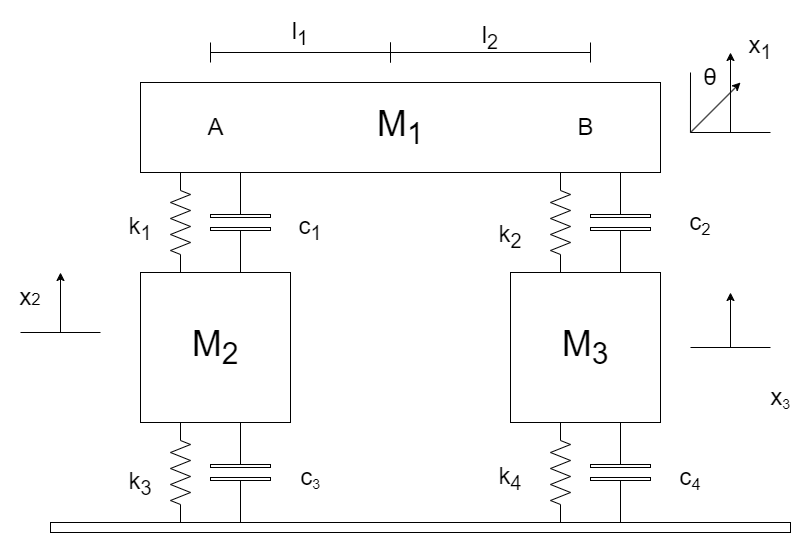

% F_A = k1*(x1-x2-L1*theta-uA)+c1*(x1_dot -x2_dot-L1*theta_dot-uA_dot)
% F_B = k2*(x1-x3-L2*theta-uB)+c2*(x1_dot -x3_dot-L2*theta_dot-uB_dot)
% 
% F2 =k3*x2 + c3*x2_dot
% F3 = k4*x3 + c4*x3_dot
F_A = k1*(x1-x2-L1*theta)+c1*(x1_dot -x2_dot-L1*theta_dot)
F_B = k2*(x1-x3-L2*theta)+c2*(x1_dot -x3_dot-L2*theta_dot)

F2 =k3*(x2-uA) + c3*(x2_dot-uA_dot)
F3 = k4*(x3-uB) + c4*(x3_dot-uB_dot)

Create Equations based on these forces & newtons 2nd law

EQ_2 = m2*x2_ddot == F_A - F2
EQ_3 = m3*x3_ddot == F_B - F3


EQ_1 = m1 * x1_ddot - (F_A + F_B)

Create the equation for the roll of the rig

EQ_1_Roll = I1 * theta_ddot == F_A*L1-F_B*L2




System_EQ = [EQ_1;
             EQ_1_Roll;
             EQ_2;
             EQ_3]
matrix_format = [x1_ddot, theta_ddot,x2_ddot,x3_ddot,...
                 x1_dot, theta_dot, x2_dot, x3_dot,...
                 x1,     theta,      x2,     x3;]

[A,F_Mat] = equationsToMatrix(System_EQ,matrix_format)
M_Mat = A(:,1:4)
C_Mat = A(:,5:8)
K_Mat = A(:,9:12)





### Creating Simulink Model for SImulated solution

% MODEL="Simulink_4DOF_Model"
% if(4==exist(MODEL))
%     close_system(MODEL,0);
%     delete(MODEL);
% end
% new_system(MODEL)
% open_system(MODEL)
%  matlabFunctionBlock( [MODEL+'/my_M_mat'], M_Mat);
%     matlabFunctionBlock( [MODEL+'/my_C_mat'], C_Mat);    
%     matlabFunctionBlock( [MODEL+'/my_K_mat'], K_Mat);   
%     matlabFunctionBlock( [MODEL+'/my_F_col'], F_Mat);
% 
% purple_str = '[0.6, 0.6, 1]';
%     set_param([MODEL+'/my_M_mat'],'BackgroundColor',purple_str,'Position', [-325   262  -190   478]);
%     set_param([MODEL+'/my_C_mat'],'BackgroundColor',purple_str,'Position', [45   -46   180   271]);    
%     set_param([MODEL+'/my_K_mat'],'BackgroundColor',purple_str,'Position', [45   308   180   617]);
%     set_param([MODEL+'/my_F_col'],'BackgroundColor',purple_str,'Position', [610     2   735   563]);    
% 
% 
% 
% 
% 
% 








### Modal Analysis

Start off by putting actual values into all the symbolic variables

sym_list = [ m1, m2, m3, I1,...
k1, k2, k3, k4,...
c1, c2, c3, c4,...
L1, L2];
value_list = zeros(size(sym_list));

test = readtable("car_rig_data.xlsx")
for i=1:size(value_list,2)
    value_list(1,i) = test.Var2(i);
end

M = subs(M_Mat,sym_list,value_list)
C = subs(C_Mat,sym_list,value_list)
K = subs(K_Mat,sym_list,value_list)


A = inv(M)*K
[eigenVector, eigenValues] = eig(A);
[~,ind] = sort(diag(eigenValues));

eigenVector=eigenVector(:,ind);
eigenValues=eigenValues(:,ind);
wn=[4];
for i=1:size(eigenValues,1)
%    vec(:,i) = vec(:,i)/max(abs(eigenVector(:,i)));
   wn(i) = sqrt(abs(sort(eigenValues(i,i))));
    
end
wn

Testing normalisation of data. I don't really see the use.


%% Testing Normalisation of Eigen Values, should result in the same value as
tmp         = eigenVector.' * M * eigenVector;
tmp_row     =  diag(tmp)';
eVec_PHI    = eigenVector ./ sqrt( tmp_row );

Im_mat      = eVec_PHI.' * M * eVec_PHI;
w2_mat      = eVec_PHI.' * K * eVec_PHI;
w_list = sqrt( double(diag(w2_mat)) );
w_table = array2table( [abs(w_list), abs(w_list/(2*pi))], "VariableNames", {'w_radpersec', 'f_Hz'}  )

test = lvm_import("test.lvm")


$$F\_A = -c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)-k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right)$$

$$F\_B = -c_{2}\,\left(x_{\dot{3}}-x_{\dot{1}}+L_{2}\,\dot{\theta }\right)-k_{2}\,\left(x_{3}-x_{1}+L_{2}\,\theta \right)$$

$$F2 = -c_{3}\,\left(\dot{\mathrm{uA}}-x_{\dot{2}}\right)-k_{3}\,\left(\mathrm{uA}-x_{2}\right)$$

$$F3 = -c_{4}\,\left(\dot{\mathrm{uB}}-x_{\dot{3}}\right)-k_{4}\,\left(\mathrm{uB}-x_{3}\right)$$

$$EQ\_2 = m_{2}\,x_{\ddot{2}}=c_{3}\,\left(\dot{\mathrm{uA}}-x_{\dot{2}}\right)+k_{3}\,\left(\mathrm{uA}-x_{2}\right)-c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)-k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right)$$

$$EQ\_3 = m_{3}\,x_{\ddot{3}}=c_{4}\,\left(\dot{\mathrm{uB}}-x_{\dot{3}}\right)+k_{4}\,\left(\mathrm{uB}-x_{3}\right)-c_{2}\,\left(x_{\dot{3}}-x_{\dot{1}}+L_{2}\,\dot{\theta }\right)-k_{2}\,\left(x_{3}-x_{1}+L_{2}\,\theta \right)$$

$$EQ\_1 = m_{1}\,x_{\ddot{1}}+c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)+c_{2}\,\left(x_{\dot{3}}-x_{\dot{1}}+L_{2}\,\dot{\theta }\right)+k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right)+k_{2}\,\left(x_{3}-x_{1}+L_{2}\,\theta \right)$$

$$EQ\_1\_Roll = I_{1}\,\ddot{\theta }=L_{2}\,\left(c_{2}\,\left(x_{\dot{3}}-x_{\dot{1}}+L_{2}\,\dot{\theta }\right)+k_{2}\,\left(x_{3}-x_{1}+L_{2}\,\theta \right)\right)-L_{1}\,\left(c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)+k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right)\right)$$

$$System\_EQ = \begin{array}{l} \left(\begin{array}{c} m_{1}\,x_{\ddot{1}}+\sigma_{2}+\sigma_{1}+\sigma_{4}+\sigma_{3}\\ I_{1}\,\ddot{\theta }=L_{2}\,\left(\sigma_{1}+\sigma_{3}\right)-L_{1}\,\left(\sigma_{2}+\sigma_{4}\right)\\ m_{2}\,x_{\ddot{2}}=c_{3}\,\left(\dot{\mathrm{uA}}-x_{\dot{2}}\right)+k_{3}\,\left(\mathrm{uA}-x_{2}\right)-\sigma_{2}-\sigma_{4}\\ m_{3}\,x_{\ddot{3}}=c_{4}\,\left(\dot{\mathrm{uB}}-x_{\dot{3}}\right)+k_{4}\,\left(\mathrm{uB}-x_{3}\right)-\sigma_{1}-\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=c_{2}\,\left(x_{\dot{3}}-x_{\dot{1}}+L_{2}\,\dot{\theta }\right)\\ \sigma_{2}=c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)\\ \sigma_{3}=k_{2}\,\left(x_{3}-x_{1}+L_{2}\,\theta \right)\\ \sigma_{4}=k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right) \end{array}$$

$$matrix\_format = \left(\begin{array}{cccccccccccc} x_{\ddot{1}} & \ddot{\theta } & x_{\ddot{2}} & x_{\ddot{3}} & x_{\dot{1}} & \dot{\theta } & x_{\dot{2}} & x_{\dot{3}} & x_{1} & \theta & x_{2} & x_{3} \end{array}\right)$$

$$A = \left(\begin{array}{cccccccccccc} m_{1} & 0 & 0 & 0 & -c_{1}-c_{2} & L_{1}\,c_{1}+L_{2}\,c_{2} & c_{1} & c_{2} & -k_{1}-k_{2} & L_{1}\,k_{1}+L_{2}\,k_{2} & k_{1} & k_{2}\\ 0 & I_{1} & 0 & 0 & L_{2}\,c_{2}-L_{1}\,c_{1} & {L_{1}}^{2}\,c_{1}-{L_{2}}^{2}\,c_{2} & L_{1}\,c_{1} & -L_{2}\,c_{2} & L_{2}\,k_{2}-L_{1}\,k_{1} & {L_{1}}^{2}\,k_{1}-{L_{2}}^{2}\,k_{2} & L_{1}\,k_{1} & -L_{2}\,k_{2}\\ 0 & 0 & m_{2} & 0 & -c_{1} & L_{1}\,c_{1} & c_{1}+c_{3} & 0 & -k_{1} & L_{1}\,k_{1} & k_{1}+k_{3} & 0\\ 0 & 0 & 0 & m_{3} & -c_{2} & L_{2}\,c_{2} & 0 & c_{2}+c_{4} & -k_{2} & L_{2}\,k_{2} & 0 & k_{2}+k_{4} \end{array}\right)$$

$$F\_Mat = \left(\begin{array}{c} 0\\ 0\\ c_{3}\,\dot{\mathrm{uA}}+k_{3}\,\mathrm{uA}\\ c_{4}\,\dot{\mathrm{uB}}+k_{4}\,\mathrm{uB} \end{array}\right)$$

$$M\_Mat = \left(\begin{array}{cccc} m_{1} & 0 & 0 & 0\\ 0 & I_{1} & 0 & 0\\ 0 & 0 & m_{2} & 0\\ 0 & 0 & 0 & m_{3} \end{array}\right)$$

$$C\_Mat = \left(\begin{array}{cccc} -c_{1}-c_{2} & L_{1}\,c_{1}+L_{2}\,c_{2} & c_{1} & c_{2}\\ L_{2}\,c_{2}-L_{1}\,c_{1} & {L_{1}}^{2}\,c_{1}-{L_{2}}^{2}\,c_{2} & L_{1}\,c_{1} & -L_{2}\,c_{2}\\ -c_{1} & L_{1}\,c_{1} & c_{1}+c_{3} & 0\\ -c_{2} & L_{2}\,c_{2} & 0 & c_{2}+c_{4} \end{array}\right)$$

$$K\_Mat = \left(\begin{array}{cccc} -k_{1}-k_{2} & L_{1}\,k_{1}+L_{2}\,k_{2} & k_{1} & k_{2}\\ L_{2}\,k_{2}-L_{1}\,k_{1} & {L_{1}}^{2}\,k_{1}-{L_{2}}^{2}\,k_{2} & L_{1}\,k_{1} & -L_{2}\,k_{2}\\ -k_{1} & L_{1}\,k_{1} & k_{1}+k_{3} & 0\\ -k_{2} & L_{2}\,k_{2} & 0 & k_{2}+k_{4} \end{array}\right)$$

test = 15×2 table
                  Var1                     Var2   
    _________________________________    _________

    {'M1 (kg)'                      }          433
    {'M2 (kg)'                      }         56.1
    {'M3 (kg)'                      }         56.1
    {'I1 (kgm^2)'                   }         82.7
    {'K1 (N/m)'                     }        20500
    {'K2 (N/m)'                     }        20500
    {'K3 (N/m)'                     }    1.472e+05
    {'K4 (N/m)'                     }    1.472e+05
    {'C1 (Ns/m)'                    }          100
    {'C2 (Ns/m)'                    }          100
    {'C3 (Ns/m)'                    }          100
    {'C4 (Ns/m)'                    }          100
    {'L1 (m)'                       }         0.75
    {'L2 (m)'                       }         0.75
    {'torsional stiffness (kNm/rad)'}        12500


$$M = \left(\begin{array}{cccc} 433 & 0 & 0 & 0\\ 0 & \frac{827}{10} & 0 & 0\\ 0 & 0 & \frac{561}{10} & 0\\ 0 & 0 & 0 & \frac{561}{10} \end{array}\right)$$

$$C = \left(\begin{array}{cccc} -200 & 150 & 100 & 100\\ 0 & 0 & 75 & -75\\ -100 & 75 & 200 & 0\\ -100 & 75 & 0 & 200 \end{array}\right)$$

$$K = \left(\begin{array}{cccc} -41000 & 30750 & 20500 & 20500\\ 0 & 0 & 15375 & -15375\\ -20500 & 15375 & 167700 & 0\\ -20500 & 15375 & 0 & 167700 \end{array}\right)$$

$$A = \left(\begin{array}{cccc} -\frac{41000}{433} & \frac{30750}{433} & \frac{20500}{433} & \frac{20500}{433}\\ 0 & 0 & \frac{153750}{827} & -\frac{153750}{827}\\ -\frac{205000}{561} & \frac{51250}{187} & \frac{559000}{187} & 0\\ -\frac{205000}{561} & \frac{51250}{187} & 0 & \frac{559000}{187} \end{array}\right)$$

wn =          0   54.6745    9.1339   54.5715


w_table = 4×2 table
    w_radpersec     f_Hz 
    ___________    ______

           0            0
      54.675       8.7017
      9.1339       1.4537
      54.571       8.6853



lvm_import v3.1
 Importing "test.lvm"

 Segment 1:

 5 Data Columns:
 | X_Value | Disp Sprung LH (Filtered) | Disp Sprung RH (Filtered) | Disp Unsprung LH (Filtered) | Disp Unsprung RH (Filtered) | 

 Importing data from Segment 1... complete (20000 data points (rows)).


 Import complete. File has one X-Column and 1 Data Segment.



test = struct with fields:
    Decimal_Separator: '.'
            X_Columns: 'One'
                 user: '12904241'
          Description: 'Time domain data from half car drop test'
                 Date: '2023/05/17'
                 Time: '16:29:56.6015748249128048448'
             Segment1: [1×1 struct]
